DATA= readtable("Training data.xlsx","TextType","string")

DATA = 9417×2 table
             Measure_Name                                                              Description                                                 
    ______________________________    _____________________________________________________________________________________________________________

    "Bulb - Exterior"                 ""(1) 12w ledt8 lamp + 1l ballast lighting""                                                                 
    "Bulb - Exterior"                 ""(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""                                    
    "Bulb - Exterior"                 ""(1) 16.5w ledt8 lamp + 1h ballast lighting""                                                               
    "Lighting Controls - Exterior"    ""(1) 2-pole circuit dimmer lighting""                                                                       
    "VFD - Cooling"    


DATA.Measure_Name = categorical(DATA.Measure_Name)

DATA = 9417×2 table
            Measure_Name                                                             Description                                                 
    ____________________________    _____________________________________________________________________________________________________________

    Bulb - Exterior                 ""(1) 12w ledt8 lamp + 1l ballast lighting""                                                                 
    Bulb - Exterior                 ""(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""                                    
    Bulb - Exterior                 ""(1) 16.5w ledt8 lamp + 1h ballast lighting""                                                               
    Lighting Controls - Exterior    ""(1) 2-pole circuit dimmer lighting""                                                                       
    VFD - Cooling                  

summary(DATA.Measure_Name)

     Air Compressor                        63 
     Air Nozzle                             2 
     Air Sealing                          136 
     Air Source                            21 
     Appliance Removal                    113 
     Boiler                               128 
     Boiler Reset Control                  21 
     Building Operator Certification        2 
     Bulb - Exterior                      537 
     Bulb - Interior                        4 
     CHP                                   26 
     Central AC                            20 
     Chiller                               59 
     Circulator Pump                       16 
     Clothes Dryer                          8 
     Clothes Washer    

# **Boiler Reset Control**

Labeldata=DATA(ismember(DATA.Measure_Name,"Boiler Reset Control"),:)

Labeldata = 21×2 table
        Measure_Name                                                     Description                                              
    ____________________    ______________________________________________________________________________________________________

    Boiler Reset Control    ""boiler control heating""                                                                            
    Boiler Reset Control    ""boiler controls heating""                                                                           
    Boiler Reset Control    ""boiler outdoor temperature reset controls heating""                                                 
    Boiler Reset Control    ""boiler reset controls c_i | boiler reset controls (retrofit only) |  |  |  | hvac""                 
    Boiler Reset Control    ""boiler reset controls c_i | boiler reset controls (retrofit only) | boiler reset control, ga

Labeldata_D=string(Labeldata.Description)

Labeldata_D = 21×1 string array
    ""boiler control heating""
    ""boiler controls heating""
    ""boiler outdoor temperature reset controls heating""
    ""boiler reset controls c_i | boiler reset controls (retrofit only) |  |  |  | hvac""
    ""boiler reset controls c_i | boiler reset controls (retrofit only) | boiler reset control, gas hvac""
    ""boiler reset controls c_i | hvac | hvac - custom | boiler reset controls c_i | controls hot water""
    ""controls | hvac | boiler reset controls c_i | custom hvac""
    ""domestic hot water | boiler reset controls | miscellaneous | time clock  control |  |  | hot water""
    ""domestic hot water | boiler reset controls | water heater | electric time clock |  |  | hot water""
    ""hvac | controls | boiler reset controls c_i | boiler reset controls c_i | hvac - custom hot water""
    ""hvac | controls | boiler reset controls c_i | custom | boiler reset controls c_i | 336696 hvac""
    ""hvac | controls | boiler reset controls c_i | cust

   % Convert to numeric
    Labeledior2Num = pdist(Labeldata_D)

Labeledior2Num =   131.9811  379.0752  532.6997  616.9806  609.7065  455.1725  634.4131  626.0399  615.4056  583.9538  583.8030  583.6866  583.4321  583.9820  351.0513  540.2314  596.0713  559.1869  563.2664  303.0215  388.7840  529.4129  614.1449  606.8369  439.2983  628.8585  620.4103  601.5555  569.3391  569.1845  569.0650  568.8040  569.3681  340.2176  544.9303  600.3332  563.7278  567.7746  290.4014  438.4917  537.7462  551.3021  351.0698  554.1011  543.5715  547.3080  509.2053  509.0324  508.8988  508.6069


    labeledLink = linkage(Labeledior2Num,"ward")

labeledLink = 	1.0e+03 *

    0.0110    0.0120    0.0042
    0.0150    0.0220    0.0054
    0.0130    0.0230    0.0096
    0.0140    0.0240    0.0107
    0.0010    0.0020    0.1320
    0.0180    0.0190    0.2335
    0.0160    0.0210    0.2409
    0.0170    0.0200    0.2731
    0.0040    0.0050    0.3361
    0.0030    0.0070    0.3511


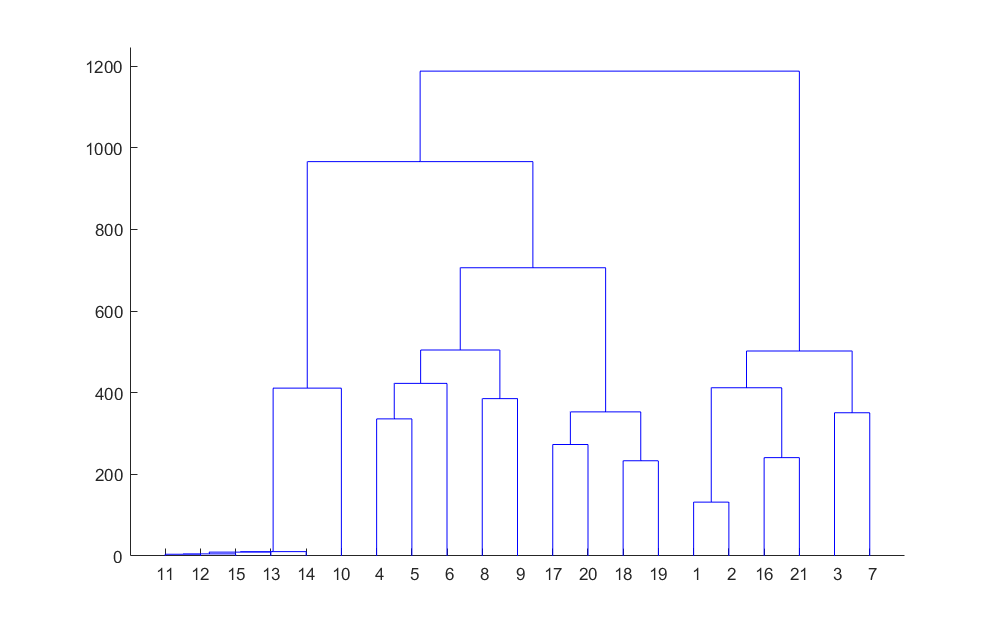

   
    % View tree
    dendrogram(labeledLink)


    % Accuracy Measure
    Labeled_ACC = cophenet(labeledLink,Labeledior2Num)

Labeled_ACC = 0.8813

    % Use inconsistency Coeff to help decide optimal # of cluster
    Labeled_I = inconsistent(labeledLink)

Labeled_I =     4.2426         0    1.0000         0
    4.7984    0.7859    2.0000    0.7071
    7.4685    2.9902    2.0000    0.7071
   10.1370    0.7836    2.0000    0.7071
  131.9811         0    1.0000         0
  233.4588         0    1.0000         0
  240.8506         0    1.0000         0
  273.0769         0    1.0000         0
  336.0774         0    1.0000         0
  351.0698         0    1.0000         0


   
   Numberofcluster=3

Numberofcluster = 3

   
     % Agglomerative Heirarichical Cluster
     Labeled_Cluster = cluster(labeledLink,"maxclust",Numberofcluster)

Labeled_Cluster =      3
     3
     3
     2
     2
     2
     3
     2
     2
     1


   
     % Assign Cluster to Measure name
     Labeled_Idx = table(Labeldata_D,Labeled_Cluster)

Labeled_Idx = 21×2 table
                                                 Labeldata_D                                                  Labeled_Cluster
    ______________________________________________________________________________________________________    _______________

    ""boiler control heating""                                                                                       3       
    ""boiler controls heating""                                                                                      3       
    ""boiler outdoor temperature reset controls heating""                                                            3       
    ""boiler reset controls c_i | boiler reset controls (retrofit only) |  |  |  | hvac""                            2       
    ""boiler reset controls c_i | boiler reset controls (retrofit only) | boiler reset control, gas hvac""           2       
    ""boiler reset contr


Cluster_1 = Labeled_Idx(Labeled_Cluster == 1,"Labeldata_D")

Cluster_1 = 6×1 table
                                                 Labeldata_D                                             
    _____________________________________________________________________________________________________

    ""hvac | controls | boiler reset controls c_i | boiler reset controls c_i | hvac - custom hot water""
    ""hvac | controls | boiler reset controls c_i | custom | boiler reset controls c_i | 336696 hvac""   
    ""hvac | controls | boiler reset controls c_i | custom | boiler reset controls c_i | 338564 hvac""   
    ""hvac | controls | boiler reset controls c_i | custom | boiler reset controls c_i | 340396 hvac""   
    ""hvac | controls | boiler reset controls c_i | custom | boiler reset controls c_i | 352620 hvac""   
    ""hvac | controls | boiler reset controls c_i | custom | boiler reset controls c_i | 356857 hvac""   


Cluster_2 = Labeled_Idx(Labeled_Cluster == 2,"Labeldata_D")

Cluster_2 = 9×1 table
                                                 Labeldata_D                                              
    ______________________________________________________________________________________________________

    ""boiler reset controls c_i | boiler reset controls (retrofit only) |  |  |  | hvac""                 
    ""boiler reset controls c_i | boiler reset controls (retrofit only) | boiler reset control, gas hvac""
    ""boiler reset controls c_i | hvac | hvac - custom | boiler reset controls c_i | controls hot water"" 
    ""domestic hot water | boiler reset controls | miscellaneous | time clock  control |  |  | hot water""
    ""domestic hot water | boiler reset controls | water heater | electric time clock |  |  | hot water"" 
    ""| boiler reset controls | boiler reset controls (retrofit only) |  | bcm |  | hvac""                
    ""| boiler reset controls | boiler reset controls (retrofit only) | 275 | tekmar co


Cluster_3 = Labeled_Idx(Labeled_Cluster == 3,"Labeldata_D")

Cluster_3 = 6×1 table
                             Labeldata_D                         
    _____________________________________________________________

    ""boiler control heating""                                   
    ""boiler controls heating""                                  
    ""boiler outdoor temperature reset controls heating""        
    ""controls | hvac | boiler reset controls c_i | custom hvac""
    ""natural gas boiler reset control heating""                 
    "hvac control boiler reset control"                          



Cluster_1_CL=preprocessText(Cluster_1.Labeldata_D)

Cluster_1_CL =   6×1 tokenizedDocument:

    12 tokens: hvac controls boiler reset controls boiler reset controls hvac custom hot water
    11 tokens: hvac controls boiler reset controls custom boiler reset controls 336696 hvac
    11 tokens: hvac controls boiler reset controls custom boiler reset controls 338564 hvac
    11 tokens: hvac controls boiler reset controls custom boiler reset controls 340396 hvac
    11 tokens: hvac controls boiler reset controls custom boiler reset controls 352620 hvac
    11 tokens: hvac controls boiler reset controls custom boiler reset controls 356857 hvac


Cluster_2_CL=preprocessText(Cluster_2.Labeldata_D)

Cluster_2_CL =   9×1 tokenizedDocument:

     8 tokens: boiler reset controls boiler reset controls retrofit hvac
    12 tokens: boiler reset controls boiler reset controls retrofit boiler reset control gas hvac
    12 tokens: boiler reset controls hvac hvac custom boiler reset controls controls hot water
    12 tokens: domestic hot water boiler reset controls miscellaneous time clock control hot water
    13 tokens: domestic hot water boiler reset controls water heater electric time clock hot water
     9 tokens: boiler reset controls boiler reset controls retrofit bcm hvac
    11 tokens: boiler reset controls boiler reset controls retrofit 275 tekmar control hvac
    10 tokens: boiler reset controls boiler reset controls retrofit 275 tekmar hvac
    10 tokens: boiler reset controls boiler reset controls retrofit d256 tekmar hvac


Cluster_3_CL=preprocessText(Cluster_3.Labeldata_D)

Cluster_3_CL =   6×1 tokenizedDocument:

    3 tokens: boiler control heating
    3 tokens: boiler controls heating
    6 tokens: boiler outdoor temperature reset controls heating
    7 tokens: controls hvac boiler reset controls custom hvac
    6 tokens: natural gas boiler reset control heating
    5 tokens: hvac control boiler reset control



N_bag1 = bagOfWords(Cluster_1_CL)

N_bag1 =   bagOfWords with properties:

          Counts: [6×12 double]
      Vocabulary: ["hvac"    "controls"    "boiler"    "reset"    "custom"    "hot"    "water"    "336696"    "338564"    "340396"    "352620"    "356857"]
        NumWords: 12
    NumDocuments: 6


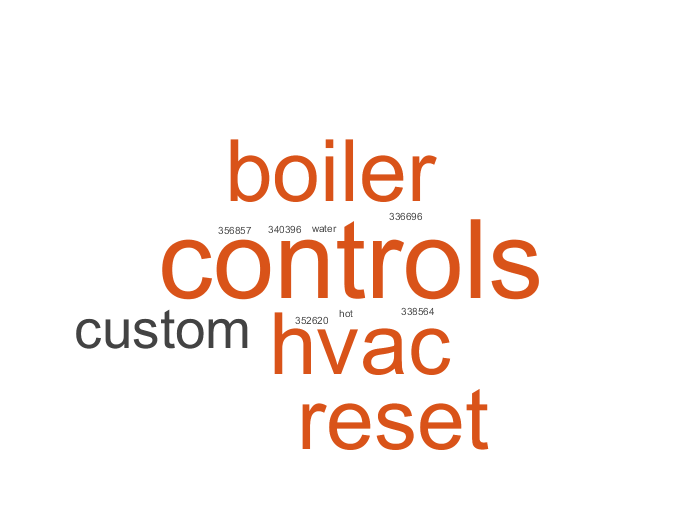

figure
NGram_CLoud1 = wordcloud(N_bag1);


N_bag2 = bagOfWords(Cluster_2_CL)

N_bag2 =   bagOfWords with properties:

          Counts: [9×20 double]
      Vocabulary: ["boiler"    "reset"    "controls"    "retrofit"    "hvac"    "control"    "gas"    "custom"    "hot"    "water"    "domestic"    "miscellaneous"    "time"    "clock"    "heater"    "electric"    "bcm"    "275"    "tekmar"    "d256"]
        NumWords: 20
    NumDocuments: 9


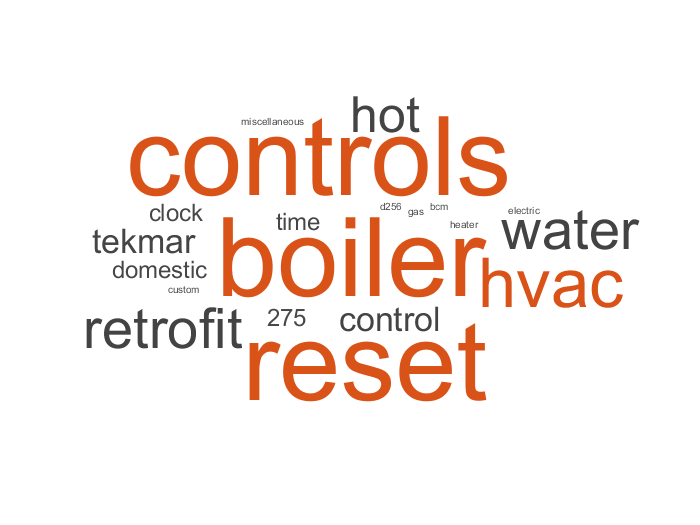

figure
NGram_CLoud2 = wordcloud(N_bag2);


N_bag3 = bagOfWords(Cluster_3_CL)

N_bag3 =   bagOfWords with properties:

          Counts: [6×11 double]
      Vocabulary: ["boiler"    "control"    "heating"    "controls"    "outdoor"    "temperature"    "reset"    "hvac"    "custom"    "natural"    "gas"]
        NumWords: 11
    NumDocuments: 6


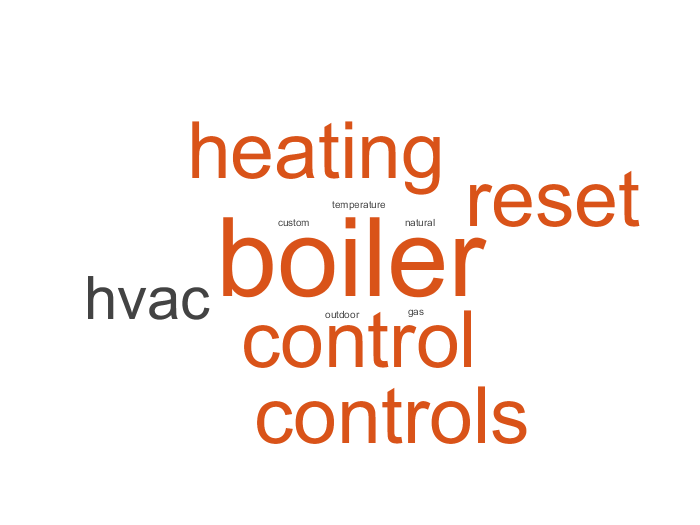

figure
NGram_CLoud3 = wordcloud(N_bag3);

function predata = preprocessText(textData)

predata=lower(textData);
predata=strtrim(predata);
predata=tokenizedDocument(predata);
predata=erasePunctuation(predata);
predata=removeStopWords(predata);
predata=removeShortWords(predata,2);

end